# Imedance matching with Chebyshev and butterworth filter network

This document allows quick computation of cascated impedance matching network following the constrain of Fano bode criterian

## Parameters

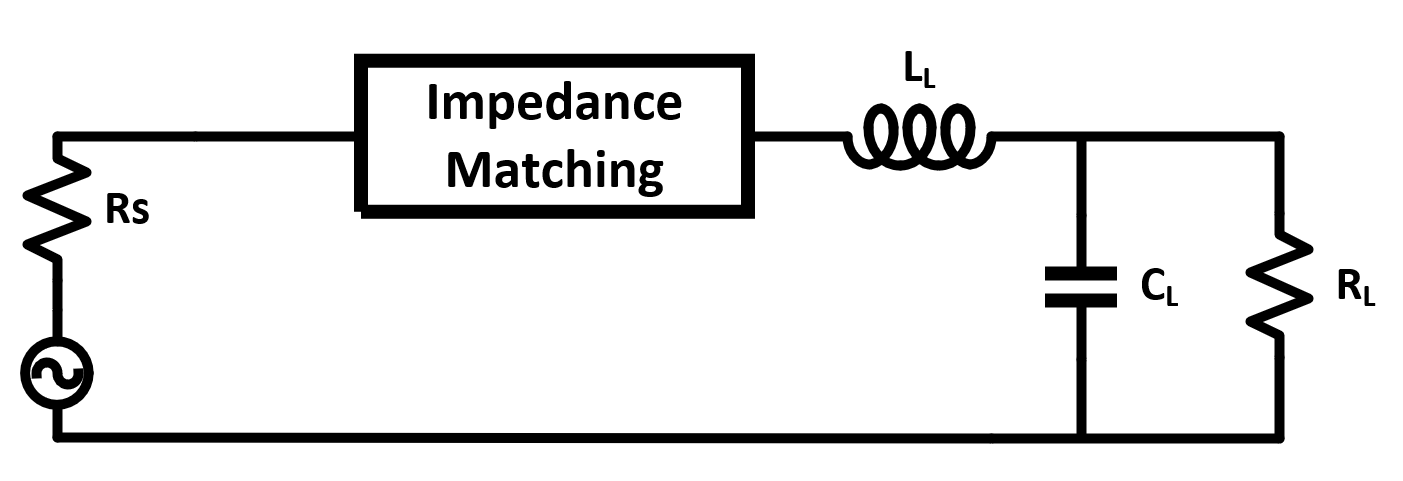

clear
e=2.718281828459045;
% this is the only part that needs user input
Rl=5000; % Load resistance
Cl=100*10^-12;%12.48*10^-12; % Load capacitance
Ll=0;%0.1*10^-6; %Load inductance
Rs=50; %source resistance
% wstart=75*10^6; %start band
% wstop=125*10^6; %stop band
Fm=5.5*10^6; %passband center frequency: 
Bw=1; %0.5; %fractional bandwidth of the passband: (wb-wa)/wm should not be greater than 2
N=3; %order of the filter, large N gives a more ideal response, but need more component

Ripple_reduction=0; 
% value from 0 to 1, 0 is the highest amount of ripple. 
% Only work for Chebyshev filter since butterworth have no ripple.
% increase this factor will rduced ripple, the trade off is less perfect matching. 

Cheby_or_but=1; %1 for chebyshev, 0 for butterworth



## Component scaling and frequency transformation 

Because we used the method of frequency transformation, we defines:

W: $\Omega \;$the angular frequency for lowpass prototype (normalized)

w: $\omega \;$the angular frequency for the final high pass circuit (normalized)

Note: both W and w are normalized around 1, the final circuit is computer using Frequency transformatoin using Fm

% Fm=(wstop+wstart)/2 %passband center frequency: 
% Bw=(wstop-wstart)/Fm %fractional bandwidth of the passband: (wb-wa)/wm
if Bw > 2
    fprintf('bandwidth %f not synthesizable, modified Bw to 2',Bw)
    Bw=2
end

% First, normalize all components with respect to load resistance
Kn=1/Rl; % component scaling factor, resulting scaled component have the same frequency response
Rl1=Rl*Kn;
Ll1=Ll*Kn;
Cl1=Cl/Kn;

% Second, since we designed our filter around unity frequency, we need transfer frequency behaviour to unity
Kf=1/(Fm*2*pi); % frequency scaling factor Kf=targeted freq/original freq
Rl2=Rl1;
Ll2=Ll1/Kf;
Cl2=Cl1/Kf;

% frequency transfering variable: lowpass prototype to bandpass prototype
wm=1; %normalized passband centre angular frequency
wa=1-Bw/2; %normalized startband angular frequency
wb=1+Bw/2; %normalized stopband angular frequency
wo=sqrt((wa^2+wb^2)/2); %arithmetic mean wo
A=((wb^2-wa^2)/2); %is a constant that sets the bandwidth
syms W w% W for lowpass, w for bandpas
W=(w^2-wo^2)/A; %relationship between W & w


## Integral restriction and termination ratios

The integral below is the Fano-Bode friterian. It represents the maximum theoretical integral restriction of the impedance matching network.

Our synthesized network should fall within this restriction 


$$\int_0^{\inf } \ln \left(\frac{1}{|\Gamma \;|}\right)d\omega =\frac{\pi \;}{R_l C_l \;}-\pi \;\sum_i \Gamma {\;}_{\textrm{ri}} \;\;\;\;\;\;\;\;\;\textrm{Eq1}\;\;\textrm{This}\;\textrm{is}\;\textrm{for}\;\textrm{parallel}\;\textrm{RC}\;\textrm{configration}\;$$



$$\int_0^{\inf } \omega {\;}^2 \;\ln \left(\frac{1}{|\Gamma \;|}\right)d\omega =\frac{\pi \;}{C_l^3 \;}\left(\frac{C_l }{L_l }-\frac{1}{3}\right)+\frac{\pi }{3}\;\sum_i \Gamma {\;}_{\textrm{ri}}^3 \;\;\;\;\;\textrm{Eq2}\;\;\;\;\;\textrm{This}\;\textrm{is}\;\textrm{for}\;\textrm{parallel}\;\textrm{RC}+\textrm{series}\;L\;\textrm{configration}\;$$


% When Ll=0, Eq2 does becomes infinity, so we use Eq1 when Ll=0

Fano=pi/(Rl2*Cl2)  %Ll=0 use eq1

Fano =    0.181818181818182



Fano2=pi/Cl2^3*(Cl2/Ll2-1/3) % Ll != 0, use eq 2

Fano2 =    Inf



flag=0

flag =      0


if Fano2<Fano %check if the second integral is satisified 
    Fano=Fano2;
    flag=1;
    fprintf('seonc fano criteria smaller than the first, choose the smaller one')
end


## Evaluate Chebyshev and Butterworth integral

In the section above, we found the maximum integral restriction. Now we evaluate the integral result of our filter polynomial to makes sure it is with in the Fano-Bode criterian.

We need to make sure that our design is just at the edge of the Fano-Bode criterian. This makes sure that we are taking the maximum bandwidth advantage. 

It also makes sure that the synthesized network have the same Cl and Ll, since we can't change those values. We need to evaluate the integrals below:


$$\int_0^{\inf } \ln \left(\frac{1}{|\Gamma \;|}\right)d\omega \;\;\;\;\;\;\;\;\textrm{Eq3}\;\;\textrm{This}\;\textrm{is}\;\textrm{for}\;\textrm{parallel}\;\textrm{RC}\;\textrm{configration}\;$$



$$\int_0^{\inf } \omega {\;}^2 \;\ln \left(\frac{1}{|\Gamma \;|}\right)d\omega \;\;\;\;\textrm{Eq4}\;\;\;\;\;\textrm{This}\;\textrm{is}\;\textrm{for}\;\textrm{parallel}\;\textrm{RC}+\textrm{series}\;L\;\textrm{configration}\;$$



$$\textrm{We}\;\textrm{know}\;\textrm{that}:\;|\Gamma |^2 =1-|S_{21} |^2 =\frac{\delta +{\epsilon {\;}^2 C}_n^2 }{1+\delta +\epsilon {\;}^2 C_n^2 }\;\to |\Gamma |=\sqrt{\frac{\delta +{\epsilon {\;}^2 C}_n^2 \left(\Omega \;\right)}{1+\delta +\epsilon {\;}^2 C_n^2 \left(\Omega \;\right)}\;}$$



$$\textrm{Butterworth}:C_n =\Omega \;{\;}^{2N} \to |\Gamma |=\sqrt{\frac{\delta +\epsilon {\;}^2 \Omega \;{\;}^{2N} }{1+\delta +\epsilon {\;}^2 \Omega \;{\;}^{2N} }\;}\;$$



$$\textrm{Chebyshev}:C_n \left(\Omega \;\right)=$$
 
$$\left\lbrace \begin{array}{ll}
\cosh^2 \left(N\;\cosh^{-1} \left(\Omega \;\right)\right) & \textrm{for}\;1\le \Omega \le \infty \;\\
\cos^2 \left(N\;\cos^{-1} \left(\Omega \;\right)\right) & \textrm{for}\;0\le \Omega \le 1
\end{array}\right.$$


           
$$\textrm{Or}:\;\;C_o \left(\Omega \;\right)=1\;$$


           
$$\;\;\;\;\;\;\;\;\;\;\;C_1 \left(\Omega \;\right)=\Omega \;\;$$


           
$$\;\;\;\;\;\;\;\;\;\;\;C_n \left(\Omega \;\right)=2\Omega C_{n-1} \left(\Omega \;\right)-C_{n-2} \left(\Omega \;\right)$$


Both forms are equivalent. We use the second form for integral analysis since arccosh() and arccos() are often undefined.


syms Cn d G ep% Cn, delta, G=1/gamma, epsilon^2

if Cheby_or_but ==0 %butterworth
    Cn=W^(N); 
else                %chebyshev
    if N==0
        Cn=1;
    elseif N==1
        Cn=W;
    else
        Cn1=W; %Cn-1 seeds for the recursion 
        Cn2=1; %Cn-2
        for i=1:N-1 %compute the correct polynomial based on the order N using recursion relation
            Cn=2*W*Cn1-Cn2;
            Cn2=Cn1; %update seed value
            Cn1=Cn;  %update seed value
        end
    end
end

## Termination ratio, delta and epsilon

standard synthesis process does not allow one to define termination ratio easily.

We choose the following equation


$$S_{21} \left(\frac{\left(0-\omega {\;}_0 \right)}{A}\right)=\frac{4r}{{\left(r+1\right)}^2 \;}\;\;$$


$\textrm{Thus}:\frac{1}{S_{21} \left(\frac{0-\omega {\;}_0 }{A}\right)}=1+\delta +\epsilon {\;}^2 C_n^2 \left(\frac{\left(0-\omega {\;}_0 \right)}{A}\;\right)$=$=\frac{{\left(r+1\right)}^2 }{4r\;}$

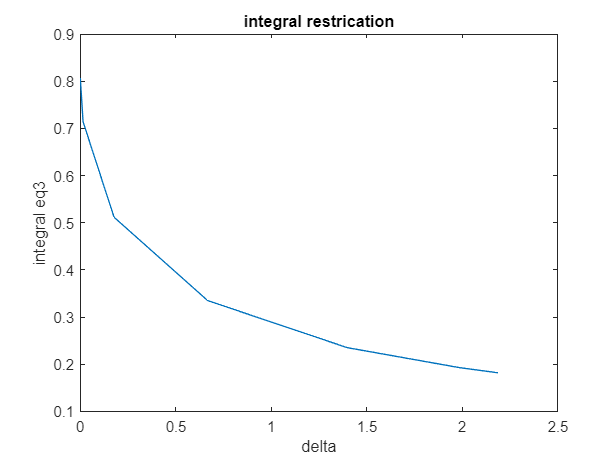


r=Rl/Rs; % the termination ratio

% evaluate Cn((0-w0)/A)
w=0; %when frequency=0
Cn0=double(subs(Cn)); % this is Cn((0-w0)/A)
syms w s%return symbolyc variable w

%express epsilon in terms of delta
ep=(((r+1)^2)/(4*r)-1-d)/Cn0^2; %this is epsilon^2

%find 1/gamma
G=log(sqrt((1+d+ep*Cn^2)/(d+ep*Cn^2)));

%intiial delta value,using newton's method to find the value%
attempt=10; %numbers of attempt in iteration
G1=subs(G);
x=zeros(1,attempt);
y=zeros(1,attempt);
d=0.0001; 


if flag==0
    %integ=double(int(G1,w,0,inf)); analytical integral
    integ3=vpaintegral(G1,0,inf); % numerical integral, it is much much faster than analytical integral
    a1=double(subs(integ3));
    a2=double(subs(integ3));
    if Fano<a1 % else we already satisfied the Fano-Bode criterian, break the loop
        for i=1:attempt
            x(i)=d; %store it for latter plotting 
            a1=double(subs(integ3));
            y(i)=a1;
            d=d*1.0001;
            a2=double(subs(integ3));
            Fp=(a2-a1)/(0.0001*x(i)); %find derivatice for newton's method 
            d=d+(Fano-a2)/Fp; %newton's method
        end
        
        %only plot when Fano<a1, otherwise there is no data to plot.
        plot(x,y,'-');
        xlabel('delta') 
        ylabel('integral eq3') 
        title('integral restrication')
    end
else
    G2=G1*w^2;
    integ3=vpaintegral(G2,0,inf); % numerical integral, it is much much faster than analytical integral
    a1=double(subs(integ3));
    a2=double(subs(integ3));
    if Fano<a1 % else we already satisfied the Fano-Bode criterian, break the loop
    for i=1:attempt
        x(i)=d; %store it for latter plotting 
        a1=double(subs(integ3));
        y(i)=a1;
        d=d*1.0001;
        a2=double(subs(integ3));
        Fp=(a2-a1)/(0.0001*x(i)); %find derivatice for newton's method 
        d=d+(Fano-a2)/Fp; %newton's method
    end
    
    %only plot when Fano<a1, otherwise there is no data to plot.
    plot(x,y,'-');
    xlabel('delta') 
    ylabel('integral eq3') 
    title('integral restrication')
    end

end



%d=0 %user defined delta, common out this line if want automatic delta!!!!!!!
ep=subs(ep); % now we can find epsilon


## Find poles

%find poles using numerical method
w=-1i*s;
Cn2=subs(Cn);
Gam_num=d+ep*Cn2^2;
Gam_den=1+d+ep*Cn2^2;
a=sym2poly(Gam_num);
b=sym2poly(Gam_den);
z=roots(a);
p=roots(b);

coeff=sqrt(a(1)/b(1))% this need to equal to one

coeff =      1



%frequency transform lowpass to bandpass configuration
pb=zeros(2,2*N);%poles for the bandpass prototype
zb=zeros(2,2*N); %zeros for the bandpass prototype

i1=1; i2=1; i3=1; i4=1;
for i=1:4*N
    if real(z(i))<0 %check for answer in the LHP
       zb(2,i1)=z(i);
       i1=i1+1;
    else 
       zb(1,i2)=z(i);
       i2=i2+1;
    end

    if real(p(i))<0 %check for answer in the LHP
       pb(2,i3)=p(i);
       i3=i3+1;
    else 
       pb(1,i4)=p(i);
       i4=i4+1;
    end
end

syms s x

num=expand(prod(s-zb(2,:)))*coeff;
den=expand(prod(s-pb(2,:)))

$$den = s^{6}+\frac{15537364614520567\,s^{5}}{18014398509481984}+\frac{5350597703205514662694219704945413\,s^{4}}{1298074214633706907132624082305024}+\frac{28623687177273716109291912334367569180155673205963\,s^{3}}{11692013098647223345629478661730264157247460343808}+\frac{1931438152834991248299998418536891205368447627275730629719432615369\,s^{2}}{421249166674228746791672110734681729275580381602196445017243910144}+\frac{331887833730115169119308126937280123956249340367838780030803825996537626725178919\,s}{237142198758023568227473377297792835283496928595231875152809132048206089502588928}+\frac{289903705199130471521926630315187342292472108742023623746140754805455057017650954519968050894705}{266998379490113760299377713271194014325338065294581596243380200977777465722580068752870260867072}$$

% den=1;num=1;
% for i=1:2*N
%     num=(s-zb(2,i))*num;
%     den=(s-pb(2,i))*den;
% end
Num=sym2poly(num);
Den=sym2poly(den);
Gamma=tf(Num,Den)

Gamma =
 
  s^6 + 0.7467 s^5 + 4.029 s^4 + 2.093 s^3 + 4.416 s^2 + 1.184 s + 1.064
  ----------------------------------------------------------------------
   s^6 + 0.8625 s^5 + 4.122 s^4 + 2.448 s^3 + 4.585 s^2 + 1.4 s + 1.086
 
Continuous-time transfer function.




index=linspace(0,2,150); %find 20 values
Gamma2=num/den; %same as Gamma, just in symbolic form
s=1i.*index;
Gamma3=subs(Gamma2); %same as Gamma, just in numerical form for 20 points
S21=1-double(abs(Gamma3)).^2; %this is s21*s21
plot(index*Fm,(S21),'LineWidth',1.6,'Color',[0 0.4470 0.7410])
hold

Current plot held


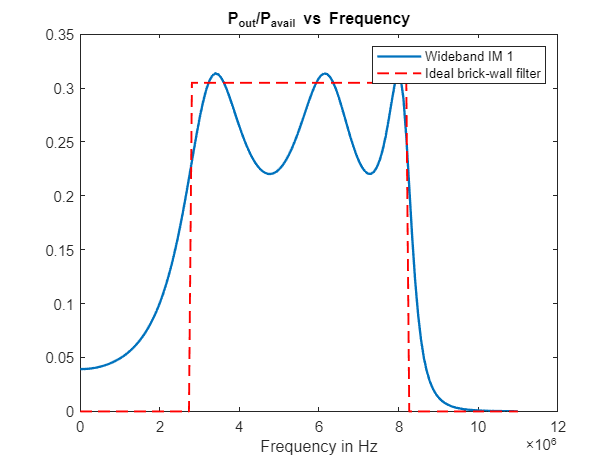


%plot what is the theoretically allowed perfect filter
D=2*pi/(Rl2*Cl2*Bw);
F=D*(heaviside(x-wa)-heaviside(x-wb));
S=1-e^(-F);
%fplot(S,[0,2],'--','LineWidth',1.3,'Color',[0.8500 0.3250 0.0980])
x=index;
Brick=subs(S);
plot(index*Fm,Brick,'--','LineWidth',1.3,'Color',[1 0 0])

legend('Wideband IM 1','Ideal brick-wall filter')
xlabel('Frequency in Hz') 
%ylabel('watts/Hz') 
title('P_{out}/P_{avail} vs Frequency')

% fplot(1/(1+ep*Cn^2),[0,2]) %use this to check if we have the right s11
% poles computed, should give same graph 


## find impedamce

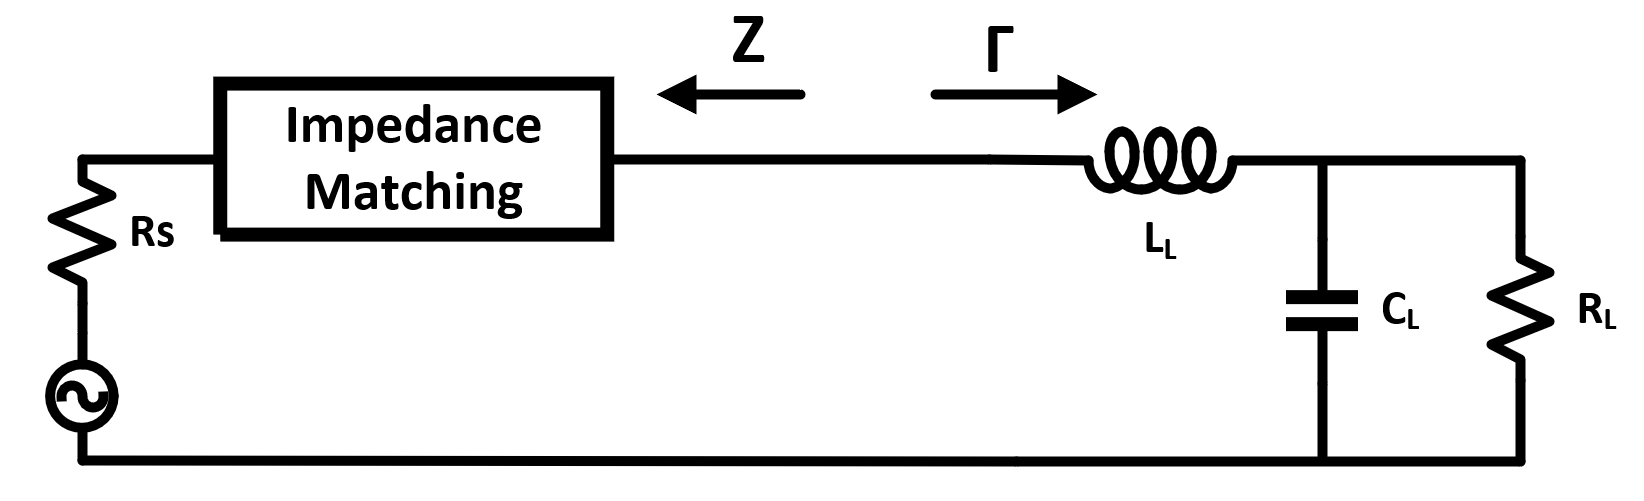


$$Z=\frac{\left(1-\Gamma \;\right)}{\left(1+\Gamma \right)}$$


num_rho_1_mapped = tf(Num,1);
den_rho_1_mapped = tf(Den,1);
Z = (den_rho_1_mapped - num_rho_1_mapped)/...
    (den_rho_1_mapped + num_rho_1_mapped)

Z =
 
  0.1157 s^5 + 0.09313 s^4 + 0.3549 s^3 + 0.1688 s^2 + 0.2154 s + 0.0215
  ----------------------------------------------------------------------
  2 s^6 + 1.609 s^5 + 8.151 s^4 + 4.541 s^3 + 9.001 s^2 + 2.584 s + 2.15
 
Continuous-time transfer function.



## Continuous fraction expansion and Causer synthesis

If we looks at the impedance Z, order of denominator is higher than that of the numerator, reason is the first element is Cl which is a parallel component

[c1, c2] = tfdata(Z);
NUM = cell2mat(c1);
DEN = cell2mat(c2);

Yn=zeros(1,2*N); %parallel component first
Zn=zeros(1,2*N); %series componetns first

for i=1:2*N
    if DEN(1)>NUM(1) %is a series element
        while (NUM(1)==0)
            NUM(:,1) = []; %remove first zero
        end
        [solution, reminder] = deconv(DEN,NUM);
        Yn(i)= solution(1,1); %is a parallel element
        DEN=NUM;
        NUM=reminder;
    elseif DEN(1)<NUM(1)
        while (DEN(1)==0)
            DEN(:,1) = [] %remove first zero
        end
        DEN(:,1) = [];
        [solution, reminder] = deconv(NUM,DEN);
        Zn(i)= solution(1,1); %is a parallel element
        NUM=DEN;
        DEN=reminder;
    end
end

Parallel=zeros(1,N);
series=zeros(1,N);

%format shortEng
i1=1; i2=1;
for i=1:2*N
    if mod(i,2)==1 %odd
        Parallel(i1)=Yn(i)/(2*pi*Fm*Rl);        
        i1=i1+1;
    else
        series(i2)=Yn(i)*(Rl/(2*pi*Fm));
        i2=i2+1;
    end
end


## fill in the parameters

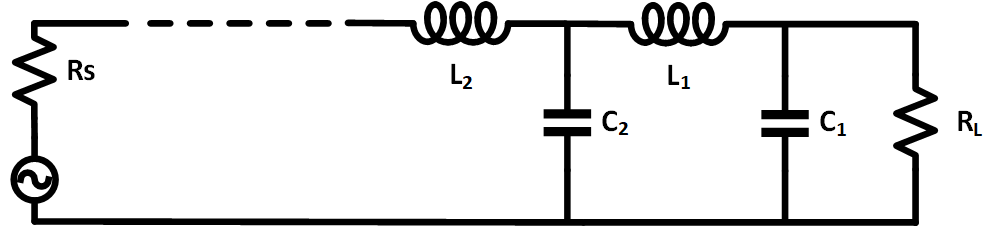


fprintf('capacitance')

capacitance

Parallel

Parallel = 	1.0e+-9 *

    0.1000    0.2239    0.3715


fprintf('inductance')

inductance

series

series = 	1.0e+-5 *

    0.8296    0.4401    0.1798


fprintf('resistance')

resistance

Res_source=solution(1,2)*Rl

Res_source =   49.999999999992141



if (Parallel(1)*1.01)<Cl
    fprintf('!!! C1<CL, consider increase delta or increase ripple reduction')
end
